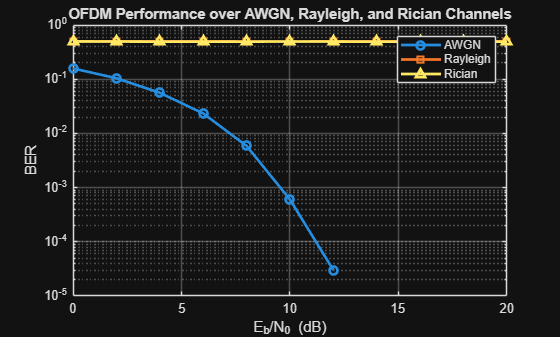

clc;
clear;
close all;

%% ----------------------------------
% PARAMETERS
%% ----------------------------------
Nbits = 1e5;          % total bits
M = 4;                % QPSK
k = log2(M);          
Nsc = 64;             % subcarriers
cp_len = 16;          
EbN0_dB = 0:2:20;

K = 5; % Rician factor

BER_awgn = zeros(size(EbN0_dB));
BER_rayleigh = zeros(size(EbN0_dB));
BER_rician = zeros(size(EbN0_dB));

%% ----------------------------------
% GENERATE BITS (SAFE LENGTH)
%% ----------------------------------
bits = randi([0 1], 1, Nbits);
bits = bits(1:floor(length(bits)/k)*k);

%% ----------------------------------
% QPSK MAPPING
%% ----------------------------------
symbols = bi2de(reshape(bits, k, []).', 'left-msb');
mod_data = qammod(symbols, M, 'UnitAveragePower', true);

%% ----------------------------------
% OFDM RESHAPE (SAFE)
%% ----------------------------------
num_symbols = floor(length(mod_data)/Nsc);
mod_data = mod_data(1:num_symbols*Nsc);
mod_data = reshape(mod_data, Nsc, num_symbols);

%% ----------------------------------
% OFDM TRANSMITTER
%% ----------------------------------
tx_ifft = ifft(mod_data, Nsc);

% Add Cyclic Prefix
tx_cp = [tx_ifft(end-cp_len+1:end, :); tx_ifft];

% Serialize
tx_signal = tx_cp(:).';

%% ----------------------------------
% LOOP OVER SNR
%% ----------------------------------
for snr_idx = 1:length(EbN0_dB)

    %% ------------------------------
    % AWGN CHANNEL
    %% ------------------------------
    rx_awgn = awgn(tx_signal, EbN0_dB(snr_idx), 'measured');

    %% ------------------------------
    % RAYLEIGH CHANNEL
    %% ------------------------------
    h_ray = (randn(size(tx_signal)) + 1j*randn(size(tx_signal))) / sqrt(2);
    rx_ray = h_ray .* tx_signal;
    rx_ray = awgn(rx_ray, EbN0_dB(snr_idx), 'measured');

    %% ------------------------------
    % RICIAN CHANNEL
    %% ------------------------------
    LOS = sqrt(K/(K+1));
    NLOS = sqrt(1/(K+1));
    h_ric = LOS + NLOS*(randn(size(tx_signal)) + 1j*randn(size(tx_signal)))/sqrt(2);

    rx_ric = h_ric .* tx_signal;
    rx_ric = awgn(rx_ric, EbN0_dB(snr_idx), 'measured');

    %% ==============================
    % RECEIVER: AWGN
    %% ==============================
    rx_parallel = reshape(rx_awgn, Nsc+cp_len, []);
    rx_no_cp = rx_parallel(cp_len+1:end, :);
    rx_fft = fft(rx_no_cp, Nsc);

    rx_symbols = rx_fft(:);
    detected = qamdemod(rx_symbols, M, 'UnitAveragePower', true);

    rx_bits = de2bi(detected, k, 'left-msb').';
    rx_bits = rx_bits(:).';

    BER_awgn(snr_idx) = sum(bits(1:length(rx_bits)) ~= rx_bits)/length(rx_bits);

    %% ==============================
    % RECEIVER: RAYLEIGH
    %% ==============================
    h_par = reshape(h_ray, Nsc+cp_len, []);
    h_no_cp = h_par(cp_len+1:end, :);
    H = fft(h_no_cp, Nsc);

    rx_parallel = reshape(rx_ray, Nsc+cp_len, []);
    rx_no_cp = rx_parallel(cp_len+1:end, :);
    rx_fft = fft(rx_no_cp, Nsc);

    rx_eq = rx_fft ./ H;

    rx_symbols = rx_eq(:);
    detected = qamdemod(rx_symbols, M, 'UnitAveragePower', true);

    rx_bits = de2bi(detected, k, 'left-msb').';
    rx_bits = rx_bits(:).';

    BER_rayleigh(snr_idx) = sum(bits(1:length(rx_bits)) ~= rx_bits)/length(rx_bits);

    %% ==============================
    % RECEIVER: RICIAN
    %% ==============================
    h_par = reshape(h_ric, Nsc+cp_len, []);
    h_no_cp = h_par(cp_len+1:end, :);
    H = fft(h_no_cp, Nsc);

    rx_parallel = reshape(rx_ric, Nsc+cp_len, []);
    rx_no_cp = rx_parallel(cp_len+1:end, :);
    rx_fft = fft(rx_no_cp, Nsc);

    rx_eq = rx_fft ./ H;

    rx_symbols = rx_eq(:);
    detected = qamdemod(rx_symbols, M, 'UnitAveragePower', true);

    rx_bits = de2bi(detected, k, 'left-msb').';
    rx_bits = rx_bits(:).';

    BER_rician(snr_idx) = sum(bits(1:length(rx_bits)) ~= rx_bits)/length(rx_bits);

end

%% ----------------------------------
% PLOT RESULTS
%% ----------------------------------
figure;
semilogy(EbN0_dB, BER_awgn, 'o-', 'LineWidth', 2); hold on;
semilogy(EbN0_dB, BER_rayleigh, 's-', 'LineWidth', 2);
semilogy(EbN0_dB, BER_rician, '^-', 'LineWidth', 2);

legend('AWGN','Rayleigh','Rician');
xlabel('E_b/N_0 (dB)');
ylabel('BER');
title('OFDM Performance over AWGN, Rayleigh, and Rician Channels');
grid on;